# **Start here:**    Numeric solution of a 2-D Partial Differential Equation 

 
editor = matlab.desktop.editor.getActive;
% Check if there is an open file
if ~isempty(editor)
    % Get the full path of the current open file
    currentFilePath = editor.Filename;
    
    % Extract the folder path from the full file path
    [currentFileFolder, ~, ~] = fileparts(currentFilePath);
    
    % Get the current working directory
    currentDir = pwd;
    
    % Check if the working directory is different from the file's folder
    if ~strcmp(currentDir, currentFileFolder)
        % Change the working directory to the file's folder
        cd(currentFileFolder);
        fprintf('Changed working directory to: %s\n', currentFileFolder);
    else
        fprintf('Already in the correct directory: %s\n', currentDir);
    end
else
    fprintf('No file is currently open in the MATLAB Editor.\n');
end

## DEMO description

This DEMO presents a case study on the Numeric solution of a  2-D Partial Differential Equation (PDE).  Specifically, we'll consider the following problem - it represents the PDE of a 2D **Steady State** heat conduction problem

- $\frac{\partial^{\;2} T}{\partial x^2 }\;\;+\;\;\frac{\partial^{\;2} T}{\partial y^2 }\;\;=\;\;0$       where $T\left(x,y\right)$ is the temperature of a plate 

Our domain is a square plate with side length $W$.  And we have a mix of both NEUMANN and DIRICHLET boundary conditions

   **BOUNDARY Conditions:**

- $\frac{\partial T}{\partial x}=0$  for $x=0\;\;\;\Longrightarrow$   **LEFT** Edge              (Nuemann)

- $\frac{\partial T}{\partial y}=0$  for $y=0\;\;\;\Longrightarrow$   **BOTTOM** Edge       (Nuemann)

- $T=2\ldotp \left|x-0\ldotp 5\right|\;\;\;\;\;\;\;\Longrightarrow \;\;\;$**TOP** Edge                (Dirichlet)

- $T=y\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Longrightarrow$   **RIGHT** Edge            (Dirichlet)

We'll solve this problem using 2 different approaches  

- via the PDE toolbox for MATLAB (this uses a **Finite Element** approach)

- via a **Finite Difference** approach - which we'll develop from scratch

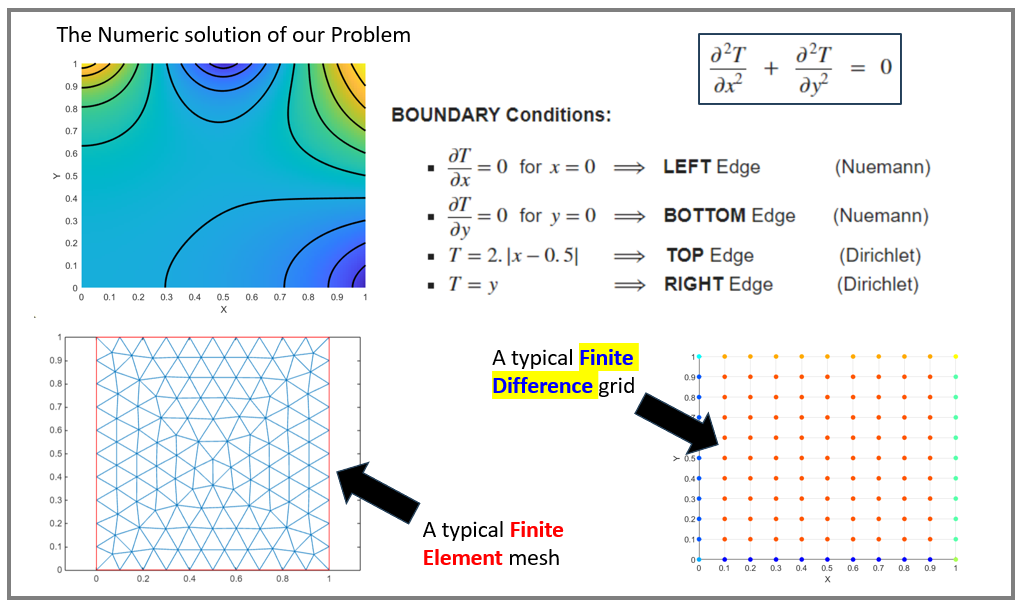

The **PDE Toolbox** solution uses a Finite Element approach to solving PDEs - and we'll use this as our "reference" solution to compare the Finite Difference solutions against. 

For the **Finite Difference** solutions we'll look at a variety of ways of managing and implementing the Finite Difference process.

- We'll introduce a data container called a [`table`](matlab:  web(fullfile(docroot, 'matlab/ref/table.html'))) as a way to construct a **lookup** table for querying NODE attributes.

- We'll introduce another data container called a [`dictionary`](matlab:  web(fullfile(docroot, 'matlab/ref/dictionary.html')))  as an even faster way to **lookup** NODE attributes.

- We'll also explore the use of a [`table`](matlab:  web(fullfile(docroot, 'matlab/ref/table.html'))) as a way to actually **store** the system equations that take the form $A\ldotp x=b$

- And we'll look at the use of [`sparse`](matlab:  web(fullfile(docroot, 'matlab/ref/sparse.html'))) matrices to more efficiently represent and solve a matrix problem of the form $A\ldotp x=b$ when the number of equations becomes large

In total we'll implement 3 different **Finite Difference** solutions:

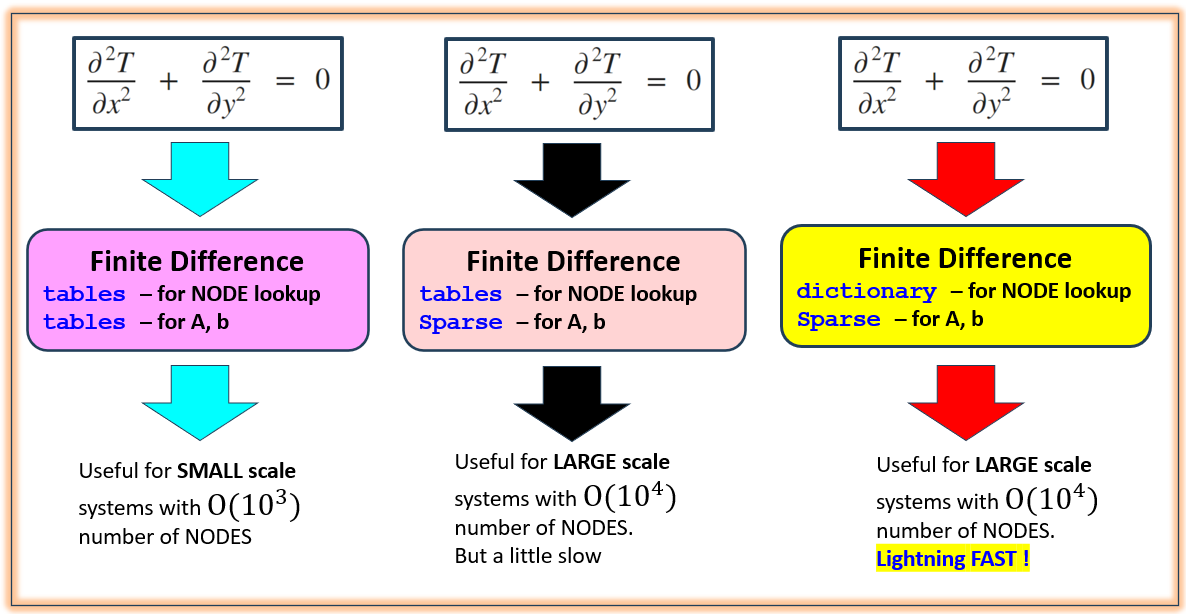

`Latest update: 12-Jul-2024`

## System Requirements

These DEMOs have been developed and tested in the **R2024a** MATLAB release.  So it is recommended that you have R2024a OR a newer release, in order to run this DEMO.

These DEMO have the following product dependencies:

- MATLAB

- Symbolic Math Toolbox

- Partial Differential Equation Toolbox

**Click** the button below to confirm you have the required release and products

 

check_install.hlp_assert_valid_install();


 ... Confirming you have <MATLAB> installed ---> [PASSED]
 ... Confirming you have <Symbolic Math Toolbox> installed ---> [PASSED]
 ... Confirming you have <Partial Differential Equation Toolbox> installed ---> [PASSED]
-------------------------------------------------- 

 ... Confirming you have a valid MATLAB release installed ---> [PASSED]
-------------------------------------------------- 


## DEMO_01:    TABLES for lookup and TABLES for storage  (SMALL scale)

Open the Live script file [`bh_solution_SMALL_scale_using_table_STORAGE.mlx`](matlab:  edit bh_solution_SMALL_scale_using_table_STORAGE.mlx).

- We'll ALSO use a data container called a [`table`](matlab:  web(fullfile(docroot, 'matlab/ref/table.html')))  as our mechanism to **"Look up" **information about our **NODES.**

- We'll use a data container called a [`table`](matlab:  web(fullfile(docroot, 'matlab/ref/table.html')))  to ***store*** our system of equations  - this makes formulating a solution **soooo easy !**

- The computed Finite Difference solution is validated against the results computed by the PDE Toolbox

 **NOTE:**   this approach is sensible for SMALL scale systems having O(100) NODES.

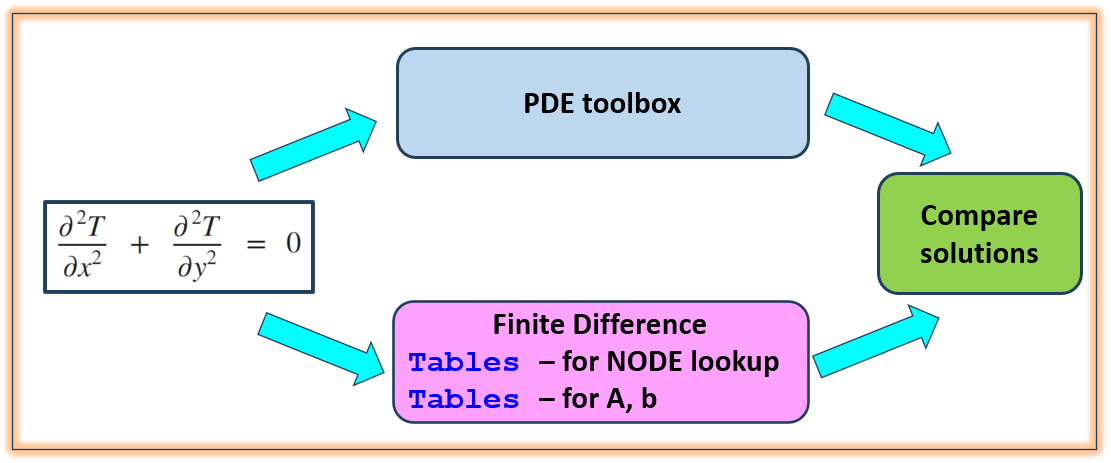

## DEMO_02:    TABLES for lookup and SPARSE for storage  (LARGE scale)

Open the Live script file [`bh_solution_LARGE_scale_using_table_LOOKUP.mlx`](matlab:  edit bh_solution_LARGE_scale_using_table_LOOKUP.mlx).

- We'll use a data container called a [`table`](matlab:  web(fullfile(docroot, 'matlab/ref/table.html')))  as our mechanism to **"Look up" **information about our nodes - this makes formulating a solution **soooo easy !**

- Because of our larger number of grid nodes, we'll utilise [`sparse`](matlab:  web(fullfile(docroot, 'matlab/ref/sparse.html'))) matrices to efficiently represent and solve a matrix problem of the form $A\ldotp x=b$

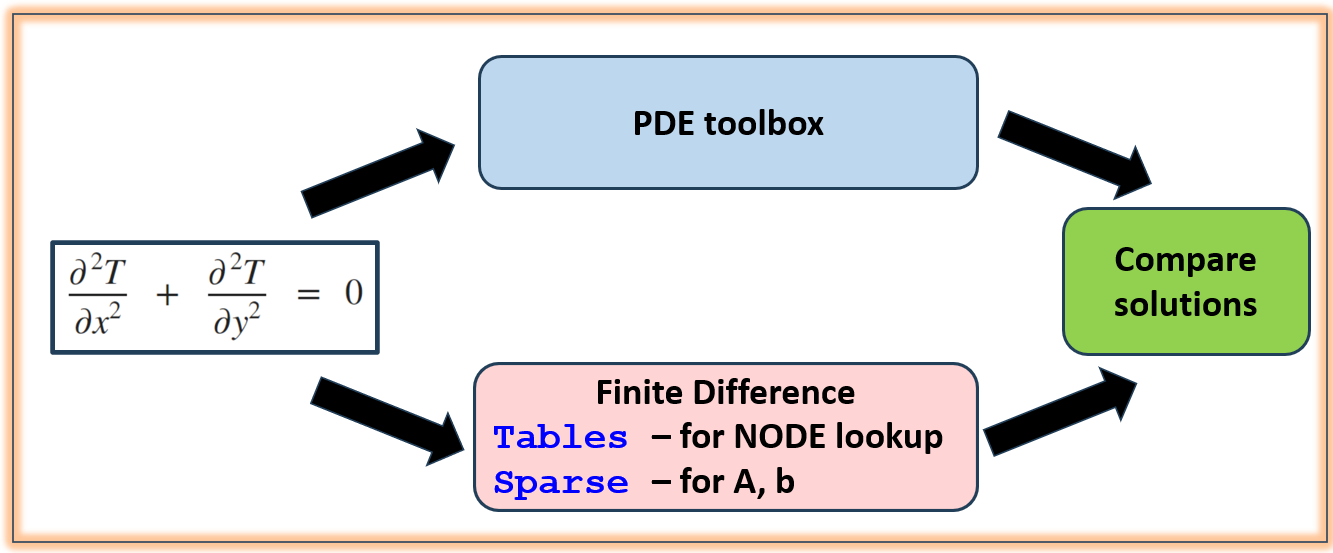

## DEMO_03:    DICTIONARY for lookup and SPARSE for storage  (LARGE scale)

Open the Live script file [`bh_solution_LARGE_scale_using_dictionary.mlx`](matlab:  edit bh_solution_LARGE_scale_using_dictionary.mlx).

- We'll use a data container called a [`dictionary`](matlab:  web(fullfile(docroot, 'matlab/ref/dictionary.html')))  as our mechanism to **"Look up" **information about our nodes - this makes formulating a solution **soooo easy !**

- A [`dictionary`](matlab:  web(fullfile(docroot, 'matlab/ref/dictionary.html'))) performs data "lookup" much ... **much faster** than a table.

- We'll utilise the [`sparse`](matlab:  web(fullfile(docroot, 'matlab/ref/sparse.html'))) matrices to efficiently represent and solve a matrix problem of the form $A\ldotp x=b$

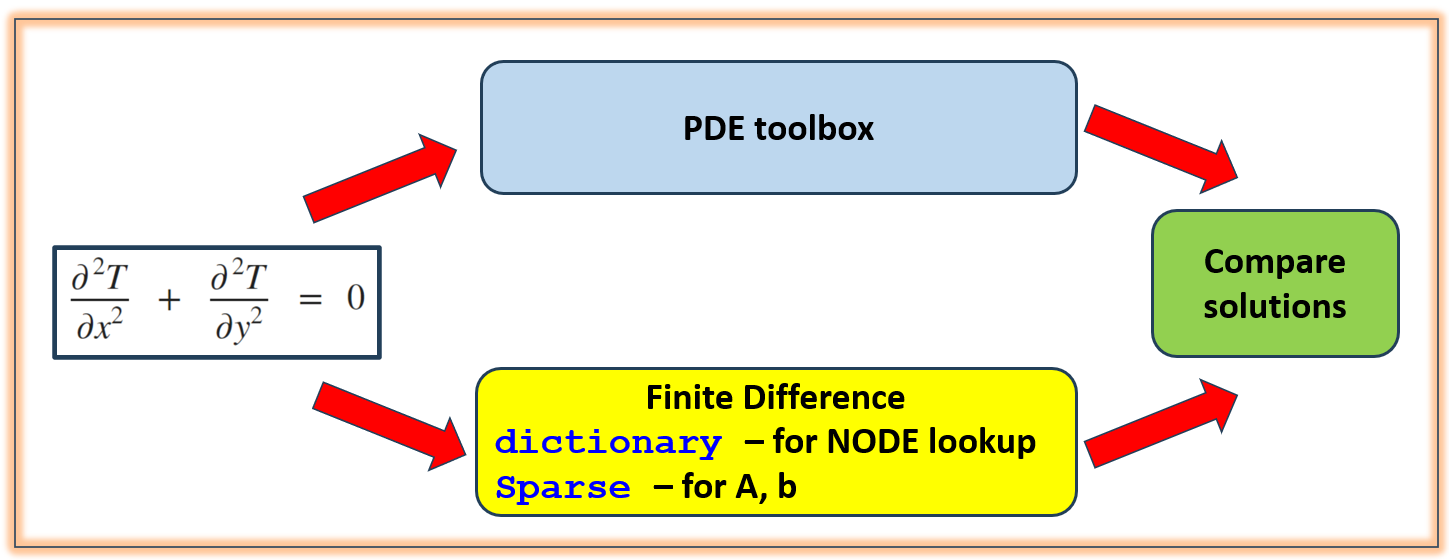

Copyright 2024 The MathWorks®, Inc.